# Actividad 1.12

Modelo cinemático de piernas

Angel Estrada Centeno - A01732584

 

H3 = 
         1         0         0        -2
         0    0.9990   -0.0457         0
         0    0.0457    0.9990         0
         0         0         0         1


 

H30 = 
    0.9981   -0.0535    0.0298     1.004
    0.0548    0.9975   -0.0441   -0.1096
   -0.0274    0.0457    0.9986   0.05482
         0         0         0         1


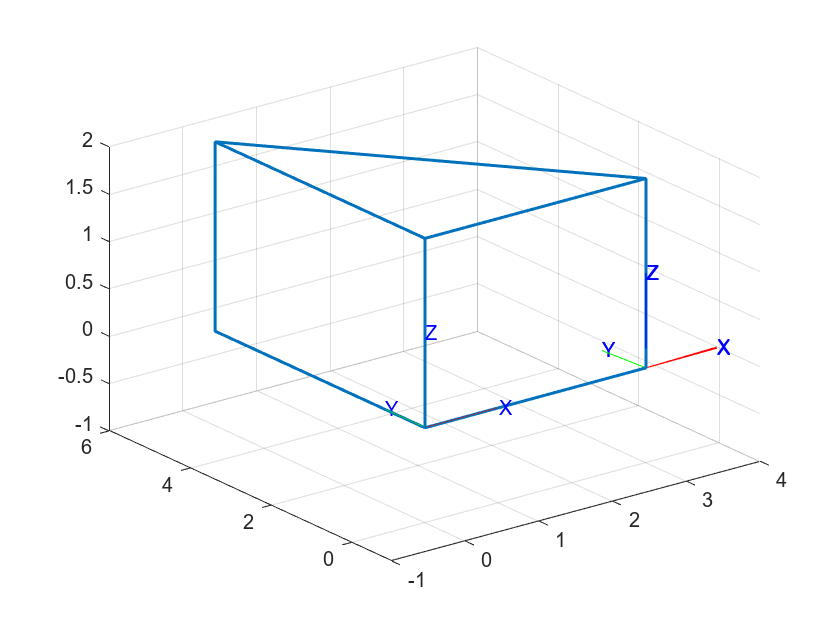

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 3]);
H2=SE3(rotx(0), [1 0 0]);
H3=SE3(rotx(0), [1 0 0]);
H4=SE3(rotx(0), [1 0 0])

H20=H1*H2;
H30= H20*H3*H4 %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 0 1 2 3];
y=[0 0 0 0 0];
z=[0 3 3 3 3];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H30)

Resultado

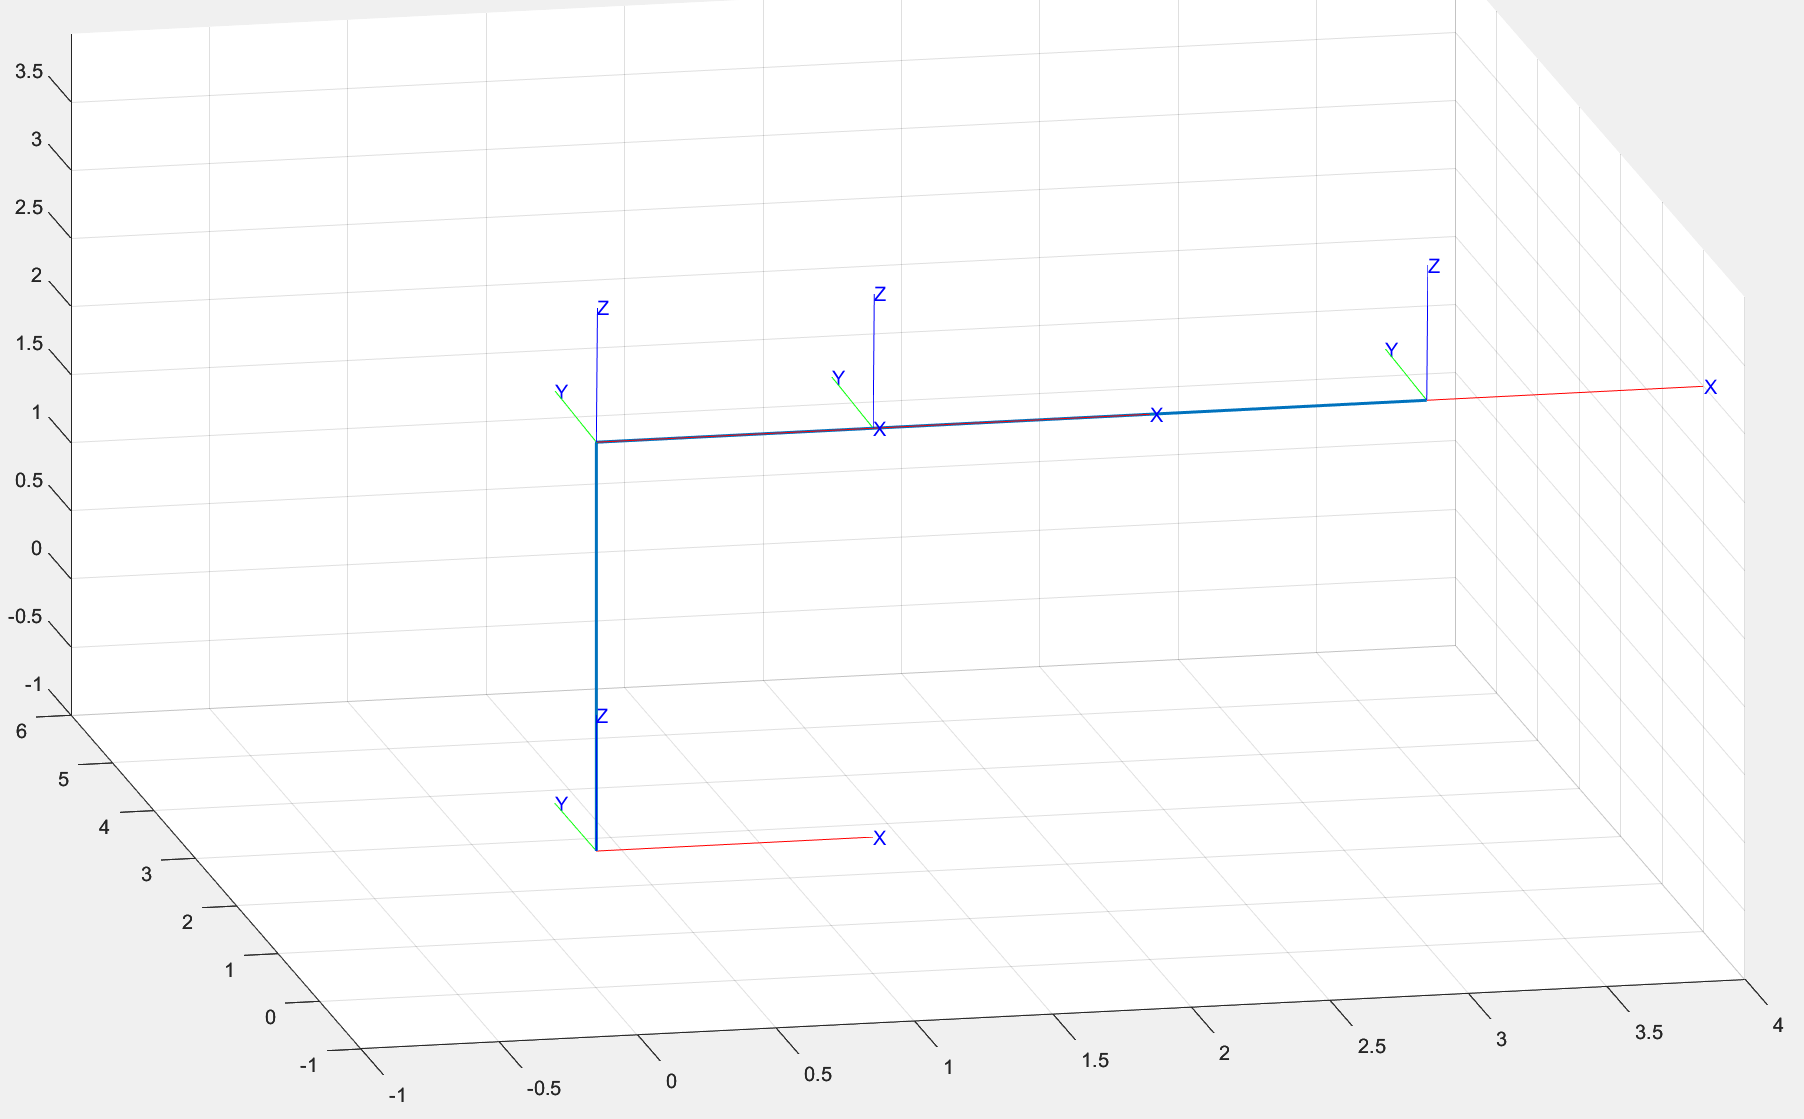

Ejercicio 2

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(pi/2), [0 0 2]);
H2=SE3(rotz(pi/2), [0 2 0]);
H3=SE3(roty(pi/2), [0 0 0]);
H4=SE3(rotz(pi/2), [1 0 0]);
H5=SE3(rotz(0), [0 0 1])

H20=H1*H2;
H30= H20*H3*H4*H5 %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 0 2 1 1];
y=[0 0 0 0 0];
z=[0 5 3 3 3];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H30)

Resultado

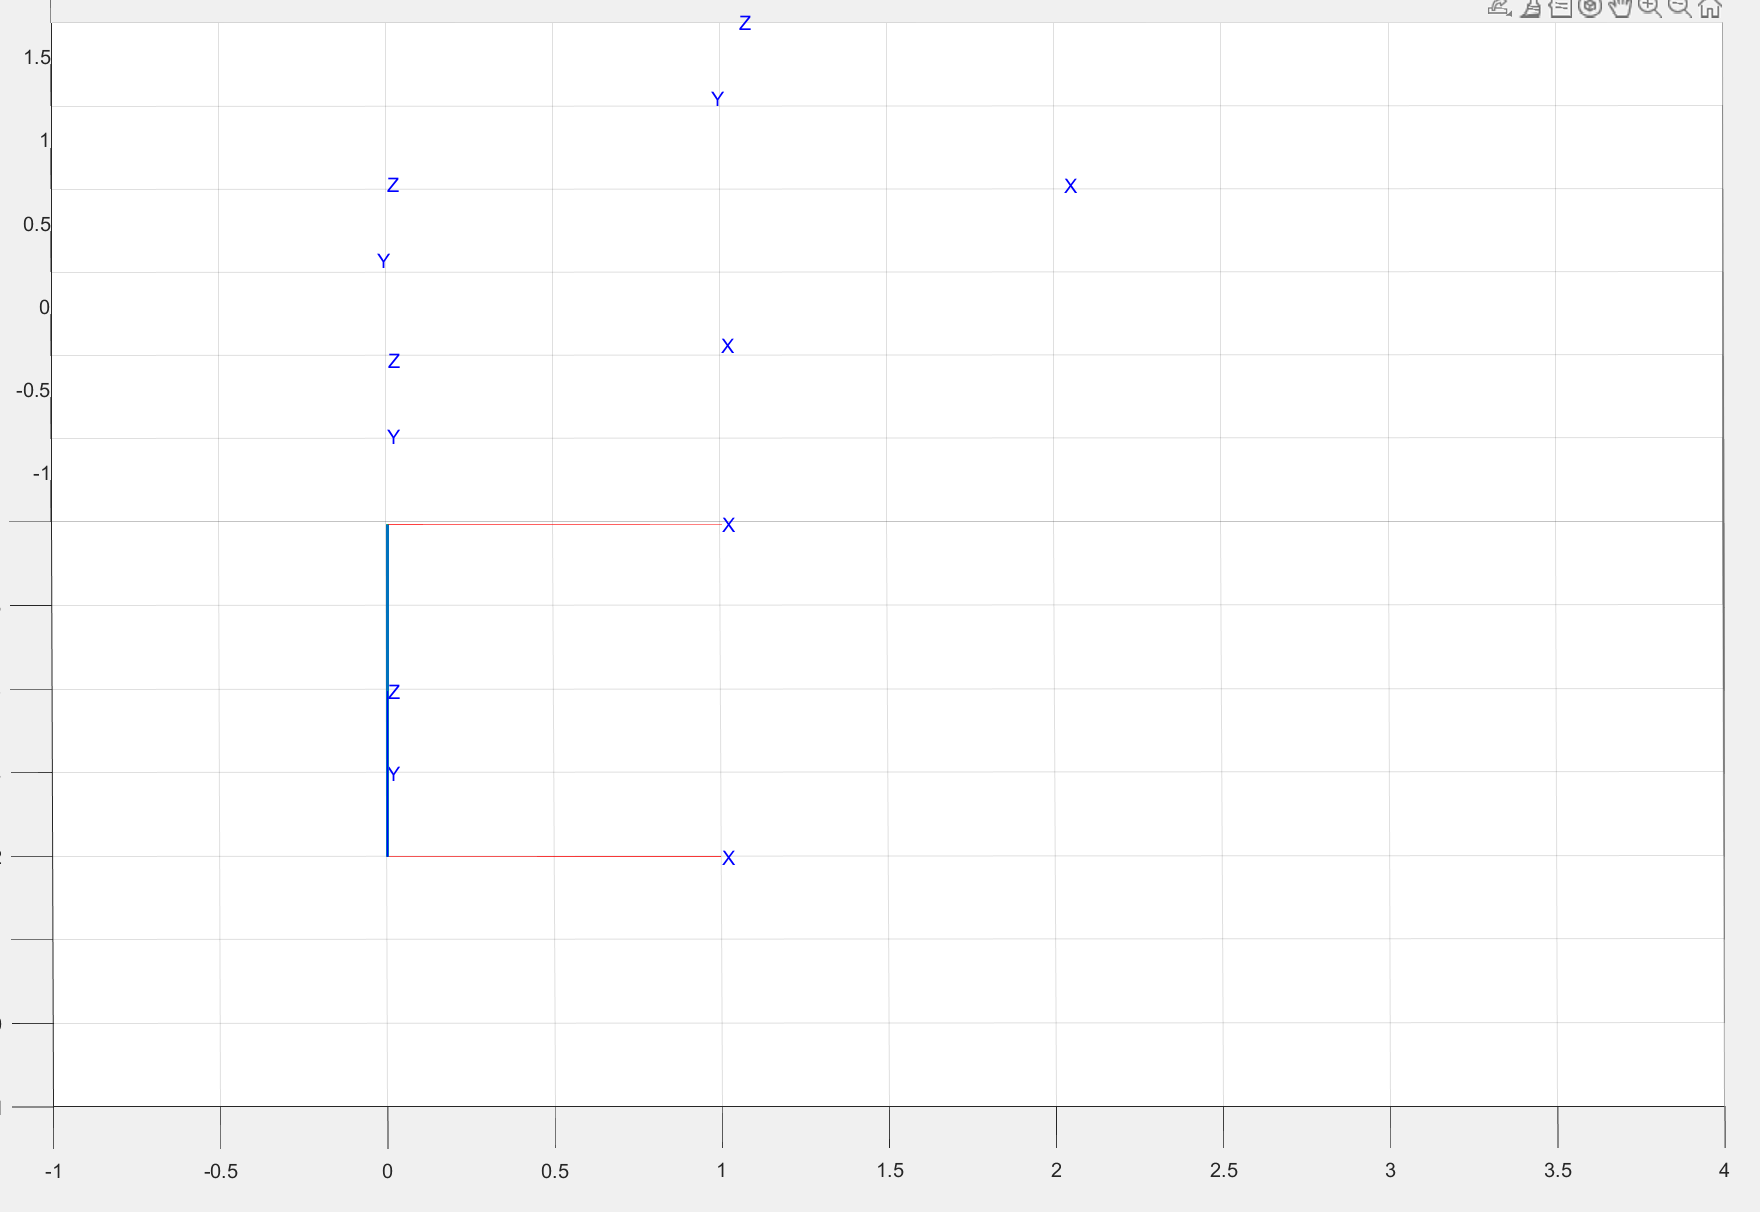

El resultado no se puede visualizar correctamente porque mi Matlab no rota el marco de referencia. 

Ejercicio 3

%Limpieza de pantalla
clear all
close all
clc

%Calculamos las matrices de transformación homogénea
H0=SE3;
H1=SE3(rotx(0), [3 0 0]);
H2=SE3(rotz(0), [0 0 -4]);
H3=SE3(roty(0), [0 3 0]);
H4=SE3(rotz(0), [0 1 0]);

H20=H1*H2;
H30= H20*H3*H4 %Matriz de transformación homogenea global de 3 a 0 

%Coordenadas de la estructura de translación y rotación
x=[0 4 4 4 4];
y=[0 0 0 4 5];
z=[0 0 -5 -5 -5];

plot3(x, y, z,'LineWidth', 1.5); axis([-1 4 -1 6 -1 2]); grid on;
hold on;

%Graficamos la trama absoluta o global 
trplot(H0,'rgb','axis', [-1 4 -1 6 -1 2])
% 
% %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H0, H1,'rgb','axis', [-1 4 -1 6 -1 2])
% %Realizamos una animación para la siguiente trama
 pause;
 tranimate(H1, H20,'rgb','axis', [-1 4 -1 6 -1 2])
% % %Realizamos una animación para la siguiente trama
 pause;
  tranimate(H20, H30,'rgb','axis', [-1 4 -1 6 -1 2])
  disp(H30)

Resultado

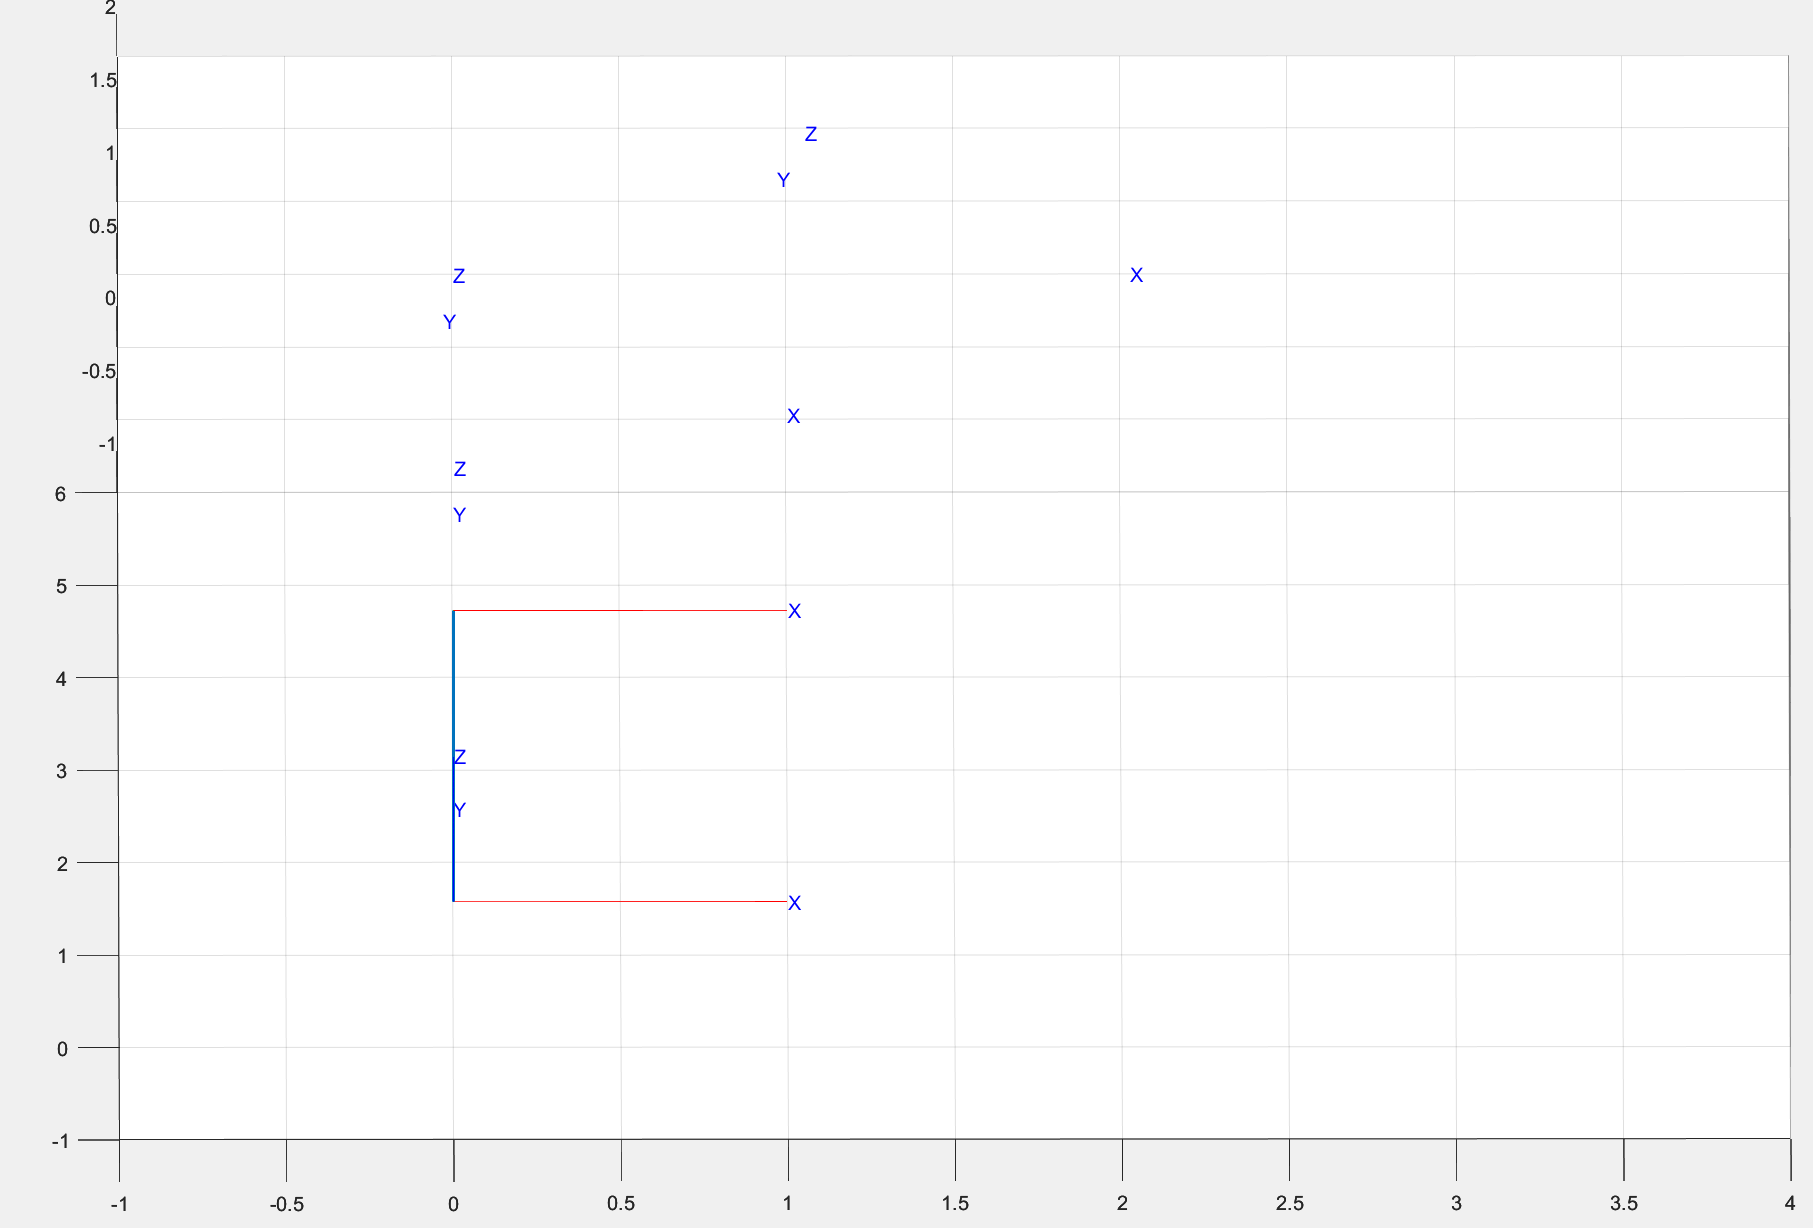

El resultado no se puede visualizar correctamente porque mi Matlab no rota el marco de referencia. 